if ~exist('binary_map','var')
    define_binary_map;
end

binary_map_inflated =   binaryOccupancyMap with properties:

   mapLayer Properties
              LayerName: 'binaryLayer'
               DataType: 'logical'
           DefaultValue: 0
    GridLocationInWorld: [0 0]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]
             Resolution: 100
               GridSize: [1000 1000]
           XLocalLimits: [0 10]
           YLocalLimits: [0 10]
           XWorldLimits: [0 10]
           YWorldLimits: [0 10]


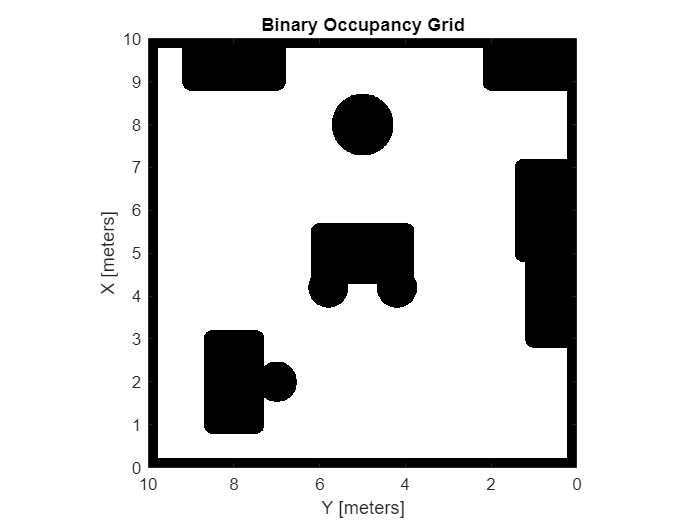


show(binary_map_inflated);
view(-90,90);

map3d = occupancyMap3D(resolution)

occ_mat = occupancyMatrix(binary_map_inflated);
[X,Y] = meshgrid(0:1/resolution:10-1/resolution,0:1/resolution:10-1/resolution);


for t = linspace(0, 2*pi, 10)
    disp(t)
    setOccupancy(map3d,[X(occ_mat) Y(occ_mat) 0*Y(occ_mat)+t],0*Y(occ_mat)+1)
end
show(map3d)
zlabel("Theta [radians]")